# Plot sensitivity Kernels (for first itaration)

**Author**: Ivan Abakumov

**Publication date**: 27th August 2018

**E-mail**: abakumov_ivan@mail.ru

FWI  sensitivity  kernels  computed  for  the first iteration of FWI utilizing 

a) diving waves only

b) full wavefield.  

Difference between b and a is shown in c)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;


## Load kernels

load([mlibfolder '/Examples/Paper_Role_of_diffractions_in_velocity_model_building/result/Kernels/Kernel_first_iteration.mat']);

## Plot results 


KERNEL = zeros(501,401,4);

KERNEL(target.xx,target.zz,1) = GradTomo;
KERNEL(target.xx,target.zz,2) = GradFWI_diving;
KERNEL(target.xx,target.zz,3) = GradFWI_diffracted;
KERNEL(target.xx,target.zz,4) = GradFWI_diffracted-GradFWI_diving;

fig = figure('Position', [900 400 570 460])

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 570 460]
       Units: 'pixels'

  Show all properties


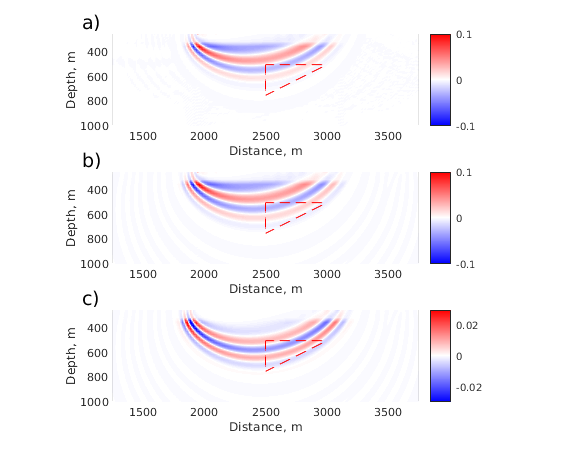


subplot(3,1,1)
pcolor(G.xx, G.zz, KERNEL(:,:,2)');
shading interp
caxis([-0.1 0.1])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(1000,150,'a)','FontSize',14)

subplot(3,1,2)
pcolor(G.xx, G.zz, KERNEL(:,:,3)');
shading interp
caxis([-0.1 0.1])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(1000,150,'b)','FontSize',14)

subplot(3,1,3)
pcolor(G.xx, G.zz, KERNEL(:,:,4)');
shading interp
caxis([-0.03 0.03])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(1000,150,'c)','FontSize',14)


colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%colormap('gray')


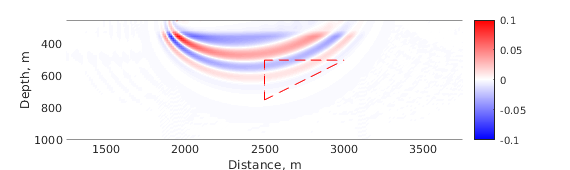

figure(1)
fig = figure('Position', [900 400 570 170]);
pcolor(G.xx, G.zz, KERNEL(:,:,2)');
shading interp
caxis([-0.1 0.1])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
%text(1000,150,'a)','FontSize',14)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

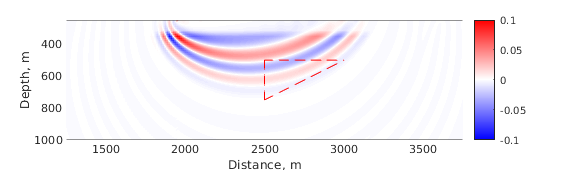



figure(2)
fig = figure('Position', [900 400 570 170]);
pcolor(G.xx, G.zz, KERNEL(:,:,3)');
shading interp
caxis([-0.1 0.1])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
%text(1000,150,'b)','FontSize',14)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

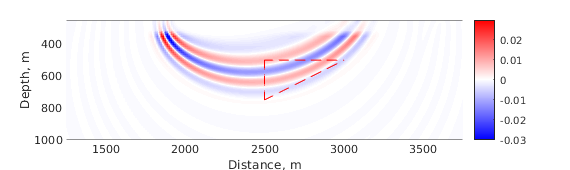



figure(3)
fig = figure('Position', [900 400 570 170]);
pcolor(G.xx, G.zz, KERNEL(:,:,4)');
shading interp
caxis([-0.03 0.03])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
%text(1000,150,'c)','FontSize',14)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%colormap('gray')

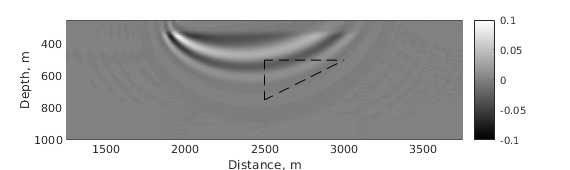


figure(21)
fig = figure('Position', [900 400 570 170]);
pcolor(G.xx, G.zz, KERNEL(:,:,2)');
shading interp
caxis([-0.1 0.1])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--k', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--k', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--k', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')

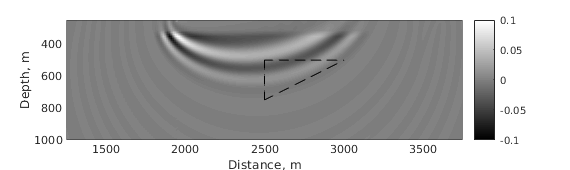



figure(22)
fig = figure('Position', [900 400 570 170]);
pcolor(G.xx, G.zz, KERNEL(:,:,3)');
shading interp
caxis([-0.1 0.1])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--k', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--k', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--k', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')

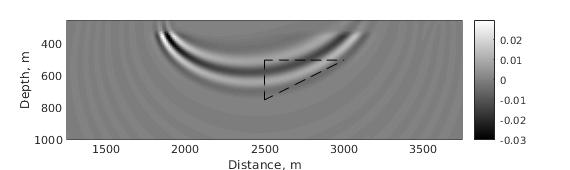



figure(23)
fig = figure('Position', [900 400 570 170]);
pcolor(G.xx, G.zz, KERNEL(:,:,4)');
shading interp
caxis([-0.03 0.03])
set(gca,'YDir', 'reverse')
hold on
%plot(acq.sx, acq.sz, 'g^')
%plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--k', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--k', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--k', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([1250 3750 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')